## **1) Load the data from a file **

- The file “MNIST.mat ” contains a training set of 4,000 handwritten digits and a test set of 1,000 handwritten digits. The images have a size of 20 by 20 grayscaleimages of digits. The 20 by 20 digit image is flattened into a 1 by 400 row vector. Each of these example digit images becomes a single row in the data. The data is already normalized in the range of [0, 1] and separated into the training set and the test data.

- Training data name: xTRain, yTRain, 

- Testing data name: xTest, yTest

- Note: There is no zero indexing in the Matlab. So the digits “1” to “9” are labeled as “1” to “9” and the digit “0 “ is labeled as “10”. 

Complete the lines of code in Section 1

%% Initialization
clear ; close all; clc

%% Setup the parameters you will use for this part of the exercise
input_feature_size  = 400;     % 20x20 Input Images of Digits
num_labels = 10;                % 10 labels, from 1 to 10. Note that "0" to label 10)

%Add code
% Load Training Data

load('MNIST.mat' );



%Add code
% Get the information of the size of the training data
[M, n] = size(XTrain);




## **2. Visualize the data**

- Display the randomly selected image samples from the training dataset.  

- The **randperm**() function in Matlab returns a row vector containing a random permutation of the integers from 1 to n.  

- Generate 48 numbers in the range of [1, 4000] using the **randperm**() function. Then, extract the image samples from the training data using the indexes generated by the **randperm**() function. 

- Display the selected image samples by calling the provided function ‘dispalyData()’. The plot is similar with the below figure. However the selected digit images will be different because the indexes are selected by the random number generator.

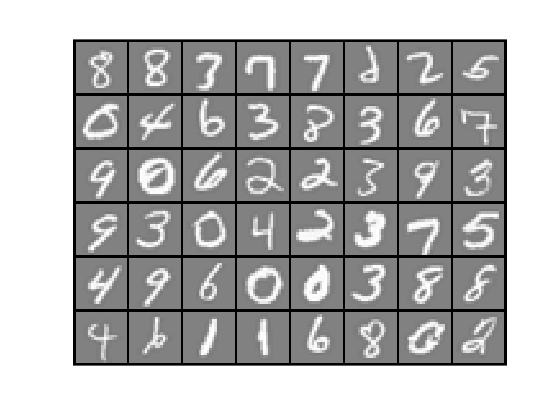



%Add code
% Generate 48  the indexes randomly in the rnage [1, number of training sample]
rand_indices = randperm(M,48);




%Add code
% Extract the image samples from the training data using the indexes generated by the randperm()

image_dispaly = XTrain(rand_indices, :);


%add code
%Display the images by calling dispalyData() fucntion

displayData(image_dispaly);

## **3. Add Bias term and intialize the othe parameters**

The “**bias term**” or “intercept parameter” allows us to move the linear model along the y-axis. 

%add code
%add bias term

bias = ones(M,1);
X = [bias, XTrain];

%Initalize the parameters for the training
[numSample,numFeature]=size(XTrain);
lambda =3 ;
alpha = 0.1;
iteration = 8000;
%iteration = 500;

all_Weight = zeros(num_labels, numFeature + 1);
Cost_J = zeros(num_labels,iteration);         %cost fucntion J


## **4. Training the one-vs-all classifier to find parameters using gradient descent**

- To implement the one-vs-all classifier, multiple regularized logistic regression classifiers are trained one for each of  C classes. 

- Each classifier is trained independently using a “ for”- loop  from t=1 to C. To do this, all class t  labels as positive samples (y=1) and all other classes as negative samples (y=0).


%iteration = 100;
tempError = [];
for L = 1: num_labels
    
    %add code here
    y= (yTrain == L);
    
    W = zeros((numFeature+1),1); % starting with zeros in W
    
    for i = 1: iteration
        Z= X*W; % 1) linear model output with current W
        prediction =sigmoid(Z); %2) You need to define sigmoid function
        error = prediction - y; %3) Calculate Error
        %tempError = [tempError, error];
        
        tempW = W;
        tempW(1) = 0;
        
        partial_delta_W = (error' * X ./numSample);
        reg_delta_W = (lambda/numSample).*tempW';
        delta_w = (partial_delta_W)+(reg_delta_W);%IS THIS IGNORING THE BIAS TERM FOR W??? % 4) partial derivatives of Log Loss w.r.t W
        W = W - alpha * delta_w' ; %5) weight updates
        
        
        %Cost function
        k=(y.*log(prediction))+((1-y).*log(1-prediction));
        % Add code: save the cost J at each iteration i for the later plotting
        j = sum(k);
        Cost_J(L,i) = -(1/M)*j;
        
        Regularization = (lambda/(2*numSample))*sum(W(1: end,1).^2);
        %Cost_J(L,i) = (Log_Loss_Sum)+Regularization;%6) Cost function -- Log Loss
        %}
        
        
        
    end
    
    
    all_Weight(L,:) = W';
    
end

## **5.Plot the Log Loss cost convergence graph for each classifier. **

Generate plots that shows how the cost changes over the iterations for each classifier t. You can use the ***subplot()*** function in the Matlab to display the multiple plots. 

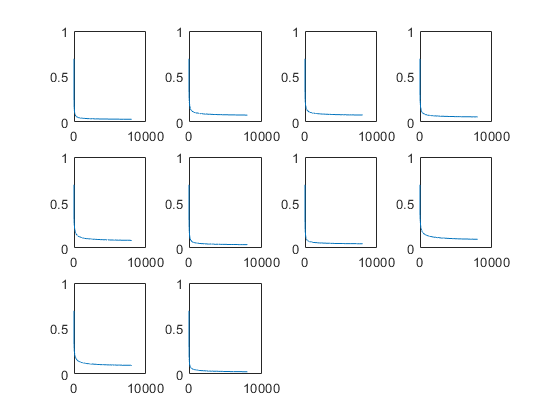

%% add code
%% Plot the Log Loss cost convergence graph for each classifier.

for i = 1:10
    subplot(3,4,i)
    plot(Cost_J(i,:))
    %changle y axis length to length of iteration
end

## **6. The training accuracy of the one-vs-all classifier **

After the training is completed, the one-vs-all classifier can predict the digit contained in a given image.  

For the given input image, the probability that the input image belongs to each class is computed using the trained logistic regression classifiers.

The one-vs-all classifier will pick the class for which the corresponding classifier outputs the highest probability. 

%%add code
%Calculate the linear model Z


%add code
%Calculate the sigmoid output of the input Z
Prob= sigmoid(X*all_Weight');



%add code
%Pick the class for which the corresponding classifier outputs the highest probability
[val, prediction] = max(Prob,[],2);




%add code
% calculate the accuracy in precentage
fprintf('\nTraining Accuracy: %.2f%%\n', mean(double(prediction == yTrain))*100);


Training Accuracy: 92.65%


**7. The one-vs-all classifier evaluation on the test data**

Add the intercept term (Bias term) in the input vector. A new input matrix is generated by concatenating the bias term vector and the new normalized input feature vector.  Make the predictions on the new testing data using the one-vs-all classifier;

- Calculate the linear model  Z                               

- Calculate the sigmoid output of the input Z

- Pick the class for which the corresponding classifier outputs the highest probability


%%add code
% Add bias term
Mtest = size(XTest,1);
x_Test = [ones(Mtest,1), XTest];


%%add code
%Calculate the linear model Z
Z = x_Test*all_Weight';


%add code
%Calculate the sigmoid output of the input Z


ProbTest = sigmoid(Z);

%add code
%Pick the class for which the corresponding classifier outputs the highest probability
[test_Val, predictionTest] = max(ProbTest,[],2);

%
% temp = (predictionTest);
% TP = 0;
% for i = 1:length(predictionTest)
%     if(temp(i)==yTest(i))
%         TP = TP+1;
%     end
% end
% acc = (TP/Mtest)*100;



%add code
% calculate the accuracy in precentage
fprintf('\nTest Accuracy: %.2f%%\n', mean(double(predictionTest == yTest))*100);


Test Accuracy: 91.20%


**8. Regularization **

Complex model (has lots of parameters) often prone to overfitting. Overfitting can be reduced by imposing a constraint on the overall magnitude of the parameters (weights),. It introduces a penalty cost term for bringing in more features with the objective function.  

• The regularized cost function in logistic regression is the log loss function with the regularized term : 

 • The parameter + controls the trade-off between training well and keeping the parameters small. When the value of  λ is large, values of the weights will be small. When the value of λ is small, values of the weights will become large.  • Train the one-vs-all classifier with different  + values. Repeat Section 4, Section 6, and Section 7 with different 7 values when  7 =1, 7=5, and  7 =10.  

- **Find the accuracies of the classifier on the training data and the testing data with teh different lambda values with lambda = [1, 5, 10]**

lambda = [1 5 10];
Mtest = size(XTest,1);

j = 3

for lam_i = 1:length(lambda)
    for L = 1: num_labels
        
        %add code here
        y= (yTrain == L);
        
        W = zeros((numFeature+1),1); % starting with zeros in W
        
        for i = 1: iteration
            Z= X*W; % 1) linear model output with current W
            prediction =sigmoid(Z); %2) You need to define sigmoid function
            error = prediction - y; %3) Calculate Error
            %tempError = [tempError, error];
            
            tempW = W;
            tempW(1) = 0;
            
            partial_delta_W = (error' * X ./numSample);
            reg_delta_W = (lambda(lam_i)/numSample).*tempW';
            delta_w = (partial_delta_W)+(reg_delta_W);%IS THIS IGNORING THE BIAS TERM FOR W??? % 4) partial derivatives of Log Loss w.r.t W
            W = W - alpha * delta_w' ; %5) weight updates
            
            
            %Cost function
            k=(y.*log(prediction))+((1-y).*log(1-prediction));
            % Add code: save the cost J at each iteration i for the later plotting
            j = sum(k);
            Cost_J(L,i) = -(1/M)*j;
            
            Regularization = (lambda(lam_i)/(2*numSample))*sum(W(1: end,1).^2);
            %Cost_J(L,i) = (Log_Loss_Sum)+Regularization;%6) Cost function -- Log Loss
            %}
            
            
            
        end
        
        
        all_Weight(L,:) = W';
        
    end
    if(lam_i == 1)
        Prob= sigmoid(X*all_Weight');
        [val, prediction] = max(Prob,[],2);
        fprintf('\nTraining Accuracy for Lambda = 1: %.2f%%\n', mean(double(prediction == yTrain))*100);
        
        
        x_Test = [ones(Mtest,1), XTest];
        Z = x_Test*all_Weight';
        ProbTest = sigmoid(Z);
        [test_Val, predictionTest] = max(ProbTest,[],2);
        fprintf('\nTraining Accuracy Lambda == 1: %.2f%%\n', mean(double(predictionTest == yTest))*100);
    end
    if(lam_i == 2)
        Prob= sigmoid(X*all_Weight');
        [val, prediction] = max(Prob,[],2);
        fprintf('\nTraining Accuracy for Lambda = 5: %.2f%%\n', mean(double(prediction == yTrain))*100);
        
        x_Test = [ones(Mtest,1), XTest];
        Z = x_Test*all_Weight';
        ProbTest = sigmoid(Z);
        [test_Val, predictionTest] = max(ProbTest,[],2);
        fprintf('\nTraining Accuracy Lambda == 5: %.2f%%\n', mean(double(predictionTest == yTest))*100);
        
    end
    if (lam_i == 3)
        Prob= sigmoid(X*all_Weight');
        [val, prediction] = max(Prob,[],2);
        fprintf('\nTraining Accuracy for Lambda = 10: %.2f%%\n', mean(double(prediction == yTrain))*100);
        
        x_Test = [ones(Mtest,1), XTest];
        Z = x_Test*all_Weight';
        ProbTest = sigmoid(Z);
        [test_Val, predictionTest] = max(ProbTest,[],2);
        fprintf('\nTraining Accuracy Lambda == 10: %.2f%%\n', mean(double(predictionTest == yTest))*100);
    end
end


Training Accuracy for Lambda = 1: 93.10%



Training Accuracy Lambda == 1: 91.40%



Training Accuracy for Lambda = 5: 92.27%



Training Accuracy Lambda == 5: 91.30%



Training Accuracy for Lambda = 10: 91.65%



Training Accuracy Lambda == 10: 90.80%
